Vytvoření melspektrogramů + uložení obrázků

% clear
% 
% folder='C:\Users\hrusk\Desktop\VŠ\5-semestr\ZOD\projekt-matlab\esc\004 - Baby cry';
% subfolder = 'C:\Users\hrusk\Desktop\VŠ\5-semestr\ZOD\projekt-matlab\esc-img\004 - Baby cry';
% audio_files = dir(fullfile(folder,'*.ogg'));
% 
% for i = 1:numel(audio_files)
%     filename=audio_files(i).name;
%     [data,Fs] = audioread(fullfile(folder,filename));
%     AudioData{i}=data(:,1);
%     f = figure;
%     melSpectrogram(AudioData{i}, Fs);
%     set(gca, 'Visible', 'off');
%     colorbar('off');
%     audio_files(i).name = audio_files(i).name(1:end-4);
%     saveas(f, fullfile(subfolder, audio_files(i).name + ".png"));
% end

clear
imageDatasetPath = fullfile('esc-img');
imds = imageDatastore(imageDatasetPath, 'IncludeSubfolders', true, 'LabelSource','foldernames');

[imdsTrain,imdsValidation] = splitEachLabel(imds, 0.7, 'randomize');

I = imread('esc-img\001 - Dog bark\1-30226-A.png');
imagesize = size(I);

numClasses = countEachLabel(imdsTrain);
numClasses = height(numClasses);

layers = [
%     imageInputLayer(imagesize)
%     convolution2dLayer(8,20,'Padding',"same")
%     batchNormalizationLayer
%     reluLayer
%     fullyConnectedLayer(numClasses)
%     softmaxLayer
%     classificationLayer

    imageInputLayer(imagesize)

    convolution2dLayer(3,12,'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding',"same")
    
    convolution2dLayer(3,2*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding',"same")
    
    convolution2dLayer(3,4*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding',"same")
    
    convolution2dLayer(3,4*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,4*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer([1 13])

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
];

options = trainingOptions('sgdm', ...
    'MaxEpochs',5, ...
    'Shuffle',"every-epoch",...
    "Plots",'training-progress',...
    "Verbose",false,...
    'ValidationData',imdsValidation,...
    'ExecutionEnvironment','cpu');

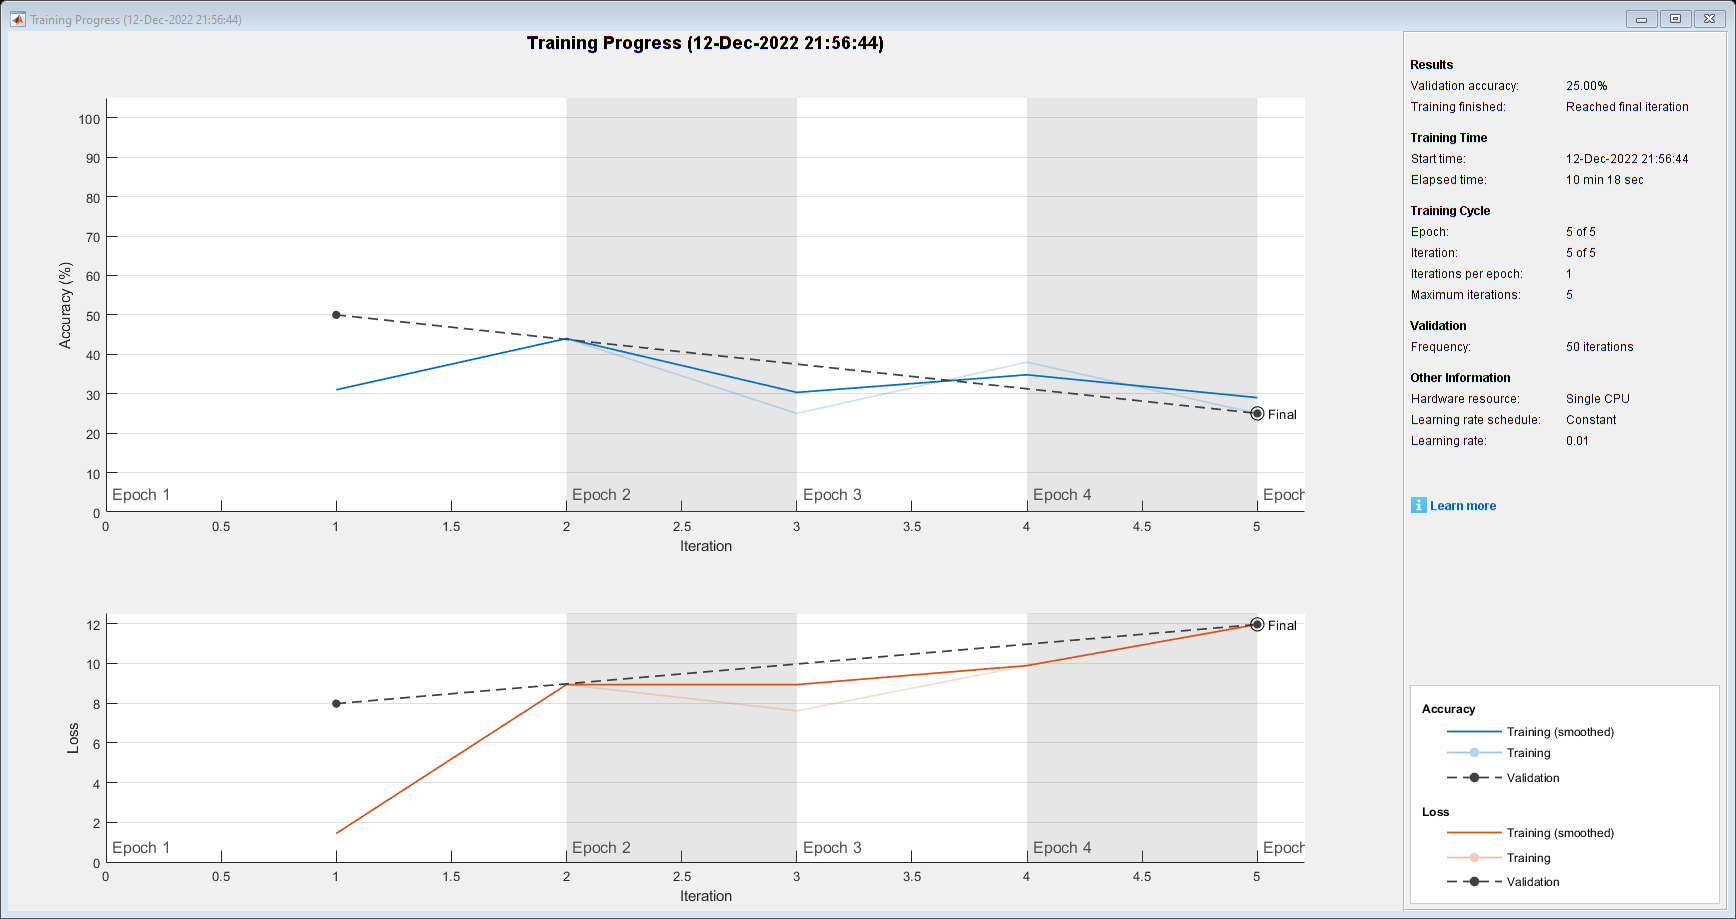

net = trainNetwork(imdsTrain, layers, options);

% Pred = classify(net, imdsValidation);

Error using nnet.internal.cnngpu.convolveBiasReluForward2D
Out of memory on device. To view more detail about available memory on the GPU, use 'gpuDevice()'. If the problem persists, reset the GPU by calling 'gpuDevice(1)'.

Error in nnet.internal.cnn.layer.util.ConvolutionReLUGPUStrategy/forward (line 29)
                Z = nnet.internal.cnngpu.convolveBiasReluForward2D( ...

Error in 

% YValidation = imdsValidation.Labels;
% accuracy = sum(Pred == YValidation)/numel(YValidation)

[baseFileName, folder] = uigetfile('*.png');
fullFileName = fullfile(folder, baseFileName);
theImage = imread(fullFileName);

Error using dir
Invalid path. The path must not contain a null character.

Error in imread>get_full_filename (line 558)
    if ~isempty(dir(filename))

Error in imread (line 374)
    fullname = get_full_filename(filename);

label = classify(net, theImage);

imshow(theImage)
title(label)